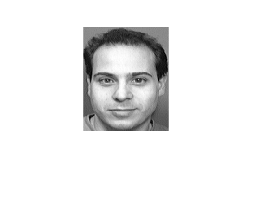

% 1. Introduction
% 1.2
folders = dir('Face\training');
folders=folders(~ismember({folders.name},{'.','..'}));
subFolders = folders([folders.isdir]);
for k = 1 : length(subFolders) 
 cur_dr=['Face\training\' subFolders(k).name];
 images=dir(cur_dr);
 images=images(~ismember({images.name},{'.','..'}));
 for i=1 : length(images)
 imshow(imread([cur_dr '\' images(i).name]));
 end
end

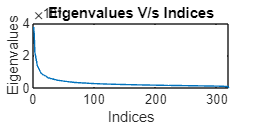

% 2. Determinig the best lower dimensional sub-space, Q1 done in this section
% 2.1 Project the training database into its correspondent eigenspace (eigenvalues and their eigenvectors) using the Matlab script 
% you wrote last session. Store the eigenvalues in a vector and sort them in a descending order.
% This means that you take your eigenvalues and their indices you found in the last lab and plot it

Img_f = [];
folders = dir('Face\training\');
folders=folders(~ismember({folders.name},{'.','..'}));
subFolders = folders([folders.isdir]);
for k = 1 : length(subFolders) 
 cur_dr=['Face\training\' subFolders(k).name];
 images=dir(cur_dr);
 images=images(~ismember({images.name},{'.','..'}));
 for i=1 : length(images)
    Imgi = imread([cur_dr '\' images(i).name]); % reads an image to a matrix
    Imgi_1 = Imgi(:,:,1); % Converts it from RGB grayscale to single matrix  Black and white
    Img_si = reshape(Imgi_1,[],1); % Coverts this into a single column matrix of size 10304 * 1
    Img_f = [Img_f Img_si]; % adds the single column matrix into final matrix
 end
end
Img_fmean = (mean(Img_f'))'; % Takes the mean of the final Image and puts in the matrix of dimension 10304 * 1
Img_fmean_rsz = reshape(Img_fmean,[112, 92]); % Resize the image into orignal dimension 112 * 92

X = [];
for j = 1:320
    Xj = cast(Img_f(:,j),"double") - Img_fmean; % subtracts the mean image from each sample
    X = [X Xj]; % Also converting the integer data type of Img_f to double
end
T = (1/320) * ((X')*X); % Using a 320*320 matrix instead of 10304*10304 matrix for getting eigenvectors and values from covariance matrix
[e_Vec_T,e_Val_T] = eig(T); % This gives eigenvectors and values of T
e_Vec_X = X * e_Vec_T; % Eigenvectors of X
e_Val_X = e_Val_T; % Eigenvalues of X are equal eigenvalues of T

[U,D,V] = svd(X); % returns U,V orthonormal column, row matrix and D a diagonal matrix containing singular values

[eig_Val_svd, I_svd] = sort(diag(D),"descend"); % Puts the eigen_Values of X in the eig_Val_svd and its Index in I_svd in descending order of eigenvalues
plot(I_svd,eig_Val_svd)
title("Eigenvalues V/s Indices")
xlabel("Indices")
ylabel("Eigenvalues")
set(gcf, 'Position', [100, 100, 1000, 500]) % The first two elements, [100, 100], specify the position of the lower left corner of the figure window in pixels.

% The next two elements, [1000, 500], specify the width and height of the figure window in pixels. gcf means getcurrent figure

% 3. Distinguishing face images from others (we choose K = 50)
% 3.1 Find the contribution of eigenfaces (from 1 to K) for each train image. (Choose the K that you reported in the previous part).
[eig_Val_c, I_c] = maxk((1/320)*diag((D.*D)),50); % Returns top 50 Eigenvalues from 1/n * D^2 diagonal matrix
eig_Face_c = U(:,I_c); % Gets the eigenfaces corresponding above eigenvalues from U matrix
W_f = [];
folders = dir('Face\training');
folders=folders(~ismember({folders.name},{'.','..'}));
subFolders = folders([folders.isdir]);
for k = 1 : length(subFolders) 
 cur_dr=['Face\training\' subFolders(k).name];
 images=dir(cur_dr);
 images=images(~ismember({images.name},{'.','..'}));
 for i = 1 : length(images)
 Imgi = imread([cur_dr '\' images(i).name]);
 Imgi_1 = Imgi(:,:,1); % Converts it from RGB grayscale to single matrix  Black and white
 Img_si = reshape(Imgi_1,[],1); % Coverts this into a single column matrix of size 10304 * 1
 W_50 = (eig_Face_c)' * (cast(Img_si, "double") - Img_fmean); % Computes the contribution of each of 50 eigenfaces for each train image
 W_f = [W_f W_50]; % vector of weights for each of trained image
 end
end
W_mean = (mean(W_f'))'; % Takes the mean of the final Weight and puts in the matrix of dimension 10304 * 1

% 3.2 Load ‘arctichare.png’ and resize it to have the same dimensions as the faces database
x_arctichare = imread("arctichare.png");
x_arctichare_gs = x_arctichare(:,:,1); % Converts it into from RGB grayscale to single channel image
x_arctichare_sz = imresize(x_arctichare_gs,[112, 92]); % Changes the size of the image from 400 * 594 to 112 * 92
x_arctichare_rs = reshape(x_arctichare_sz,[],1);

% 3.3 Find contribution of eigenfaces to  arctichare.png3 using Eq.1 and form the matrix of weights for the test image, Q2 and Q3 done in this section
W_arctichare = (eig_Face_c)' * (cast(x_arctichare_rs, "double") - Img_fmean); % Computes the contribution of each of 50 eigenfaces for arctichare image  
d_arctichare = norm(W_arctichare - W_mean)

d_arctichare = 9.8414e+03


x_test = imread("Face\testing\s2\9.png");
x_test_gs = x_test(:,:,1);
x_test_rs = reshape(x_test_gs,[],1);
W_test = (eig_Face_c)' * (cast(x_test_rs,"double") - Img_fmean);
d_test = norm(W_test - W_mean) % Eucleidian distance

d_test = 3.4621e+03


d_test_four = [];
for i = 4:7
    filename = ("Face\\testing\\s%d\\9.png");
    x_test_i = imread(sprintf(filename,i));
    x_test_i_gs = x_test_i(:,:,1);
    x_test_i_rs = reshape(x_test_i_gs,[],1);
    W_test_i = (eig_Face_c)' * (cast(x_test_i_rs,"double") - Img_fmean);
    d_test_pr = norm(W_test_i - W_mean);
    d_test_four = [d_test_four d_test_pr]
end

d_test_four = 3.2011e+03

d_test_four = 1.0e+03 *

    3.2011    4.2917


d_test_four = 1.0e+03 *

    3.2011    4.2917    5.3056


d_test_four = 1.0e+03 *

    3.2011    4.2917    5.3056    3.8737


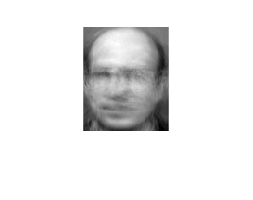

% 4.1 Face recognition using KNN
 
    W_p_mean = []; % Initializing the variables
    W_person = [];
    W_p_mean_str = [];
    p = 1;
    for j = 1:320
        W_intermediate = W_f(:,j); % Stores the column vector in the proxy array to be used later
        W_person = [W_person W_intermediate]; % Stores image vectors for each person in an array 
        
        if (mod(j,8) == 0) % Changes the person array after putting all corresponding image column vectors
            
            W_p_mean = mean(W_person,2); % Calculate mean weights for each person, here 2 means twice mean
            eig_Face_K = U(:,1:50);
            rec_img = (eig_Face_K * W_p_mean) + Img_fmean;  % Reconstructing eigenfaces using W_p_mean weights
            rec_img_rs = reshape(rec_img,[112,92]);
            rec_img_rs = (rec_img_rs - min(rec_img_rs,[],"all"))/(max(rec_img_rs,[],"all")-min(rec_img_rs,[],"all")); % Normalizing the image matrix 
            
            if j <=40
                imshow(rec_img_rs)
                imwrite(rec_img_rs,sprintf("Q4_Rec_Img%d.bmp",p)) % Showing the above process for 5 images
            end
          W_p_mean_str = [W_p_mean_str W_p_mean]; % Stores mean for further usage
          p = p + 1; 
          W_p_mean = []; % Re initialize variables for the next person data 
          W_person = [];
        end
    end


% 4.2 Loading the test dataset
W_ft = [];
folders = dir('Face\testing');
folders=folders(~ismember({folders.name},{'.','..'}));
subFolders = folders([folders.isdir]);
for k = 1 : length(subFolders) 
 cur_dr=['Face\testing\' subFolders(k).name];
 images=dir(cur_dr);
 images=images(~ismember({images.name},{'.','..'}));
 for i=1 : length(images)
     Img_i = imread([cur_dr '\' images(i).name]);
     Imgi_1 = Img_i(:,:,1); % Converts it from RGB grayscale to single matrix  Black and white
     Img_ti = reshape(Imgi_1,[],1); % Coverts this into a single column matrix of size 10304 * 1
     W_t = (eig_Face_c)' * (cast(Img_ti, "double") - Img_fmean); % Computes the contribution of each of 50 eigenfaces for each train image
     W_ft = [W_ft W_t]; % vector of weights for each of trained image
 end
end

%  4.3 Calculate Euclidean distance of the first test sample weight matrix with each of Wp_mean1,2,3,..,40, Q5 done in this section
tic % compare the complexity of th eprograms through measuring elasped time
d_small_val = [];  % Initializing the variables
pred_index = [];
target_index = [];
index_str = 1;
correct_pred = 0;

for s = 1:80   % done for all 80 images
    d_p_mean_t = [];
    W_img_t = W_ft(:,s);
    
    for j = 1:40   % eucledian dist from w_p_mean1,2,...,40         
            d_intermediate = norm(W_img_t - W_p_mean_str(:,j)); % eucledian distance between first test sample and stored mean from training dataset
            d_p_mean_t = [d_p_mean_t d_intermediate]; % storing the above eucledian distances
    end

    [d_small, I_small] = min(d_p_mean_t); % finds the index of shortest eucledian w_p_mean distance
    d_small_val(s) = d_small;
    pred_index(s) = I_small; % putting predicted index as label in array
    target_index = [target_index index_str]; % target index for each image

    if (mod(s,2) == 0) % increases the actual/target index after images from each person has been analysed
        index_str = index_str + 1;
    end

    if(pred_index(s) == target_index(s))
        correct_pred = correct_pred + 1;
    end
end

W_p_mean_shortest_1st_sample =  d_small_val(1)

W_p_mean_shortest_1st_sample = 3.2904e+03

Accuracy = correct_pred/80  % here 80 are total number of predictions, test images analysed

Accuracy = 0.8875

toc % record the tic value uptill this point

Elapsed time is 0.046994 seconds.



% 4.4 Predicting label calculate the Euclidean distance between its
% correspondent weight vector and all of 320 weight vectors of train images, Q6 done in this section
tic
K = 5;
pred_label = [];
correct_pred = 0;

for t = 1:80
    I_K = [];
    d_K = [];
    d_eucledian = [];

    for i = 1:320
        d_intermediate_6 = norm(W_ft(:,t) - W_f(:,i));
        d_eucledian = [d_eucledian d_intermediate_6];
    end
    [d_min, I_min] = mink(d_eucledian,K);
    I_K = [I_K I_min];
    d_K = [d_K d_min];
    mod_label = mode(ceil(I_K/8));
    pred_label = [pred_label mod_label];

    if(pred_label(t) == target_index(t))
        correct_pred = correct_pred + 1;
    end
end
pred_label_1st_test_image = pred_label(1)

pred_label_1st_test_image = 1

Accuracy_K = correct_pred/80  % here 80 are total number of predictions, test images analysed

Accuracy_K = 0.9000

toc

Elapsed time is 0.107207 seconds.



% 4.5 Calculate eigenfaces weights matrix for your photo and compare it with W𝑎𝑟𝑐𝑡𝑖𝑐ℎ𝑎𝑟𝑒(arctic hare image weight matrix) and 𝑾𝒎𝒆𝒂𝒏(training set weight matrix) that you had calculated before.
% Q7 done in this section

x_41 = imread("gvs1.jpg");
x_41_gs = x_41(:,:,1); % Converts it into from RGB grayscale to single channel image
x_41_rs = reshape(x_41_gs,[],1);
W_gvs = (eig_Face_c)' * (cast(x_41_rs, "double") - Img_fmean) % Computes the contribution of each of 50 eigenfaces for given image

W_gvs = 1.0e+03 *

   -1.5555
   -0.4149
   -0.2057
   -2.0599
    1.1866
   -0.2735
   -1.1374
   -0.6331
   -0.1685
   -0.2725


W_arctichare % comparing these 3 eigenface weight contribution

W_arctichare = 1.0e+03 *

    7.0912
    1.0925
    0.1702
   -0.4861
   -4.8493
    1.8142
   -0.8567
    1.8879
    1.6465
    0.0911


W_mean

W_mean = 1.0e-13 *

    0.2558
   -0.1421
         0
   -0.0568
    0.0924
    0.3588
   -0.1101
   -0.1137
    0.0853
   -0.0995



d_eucledian_gvs = [];
pred_label_gvs = [];
d_min_gvs = [];
I_min_gvs = [];

for i = 1:320
    d_intermediate_7 = norm(W_gvs - W_f(:,i));
    d_eucledian_gvs = [d_eucledian_gvs d_intermediate_7];
end

[d_min_gvs, I_min_gvs] = mink(d_eucledian_gvs,K);
pred_label_gvs = mode(ceil(I_min_gvs/8))

pred_label_gvs = 31